# Logistic regression multi classification based on Newton method

close all
clear 

## Training process:

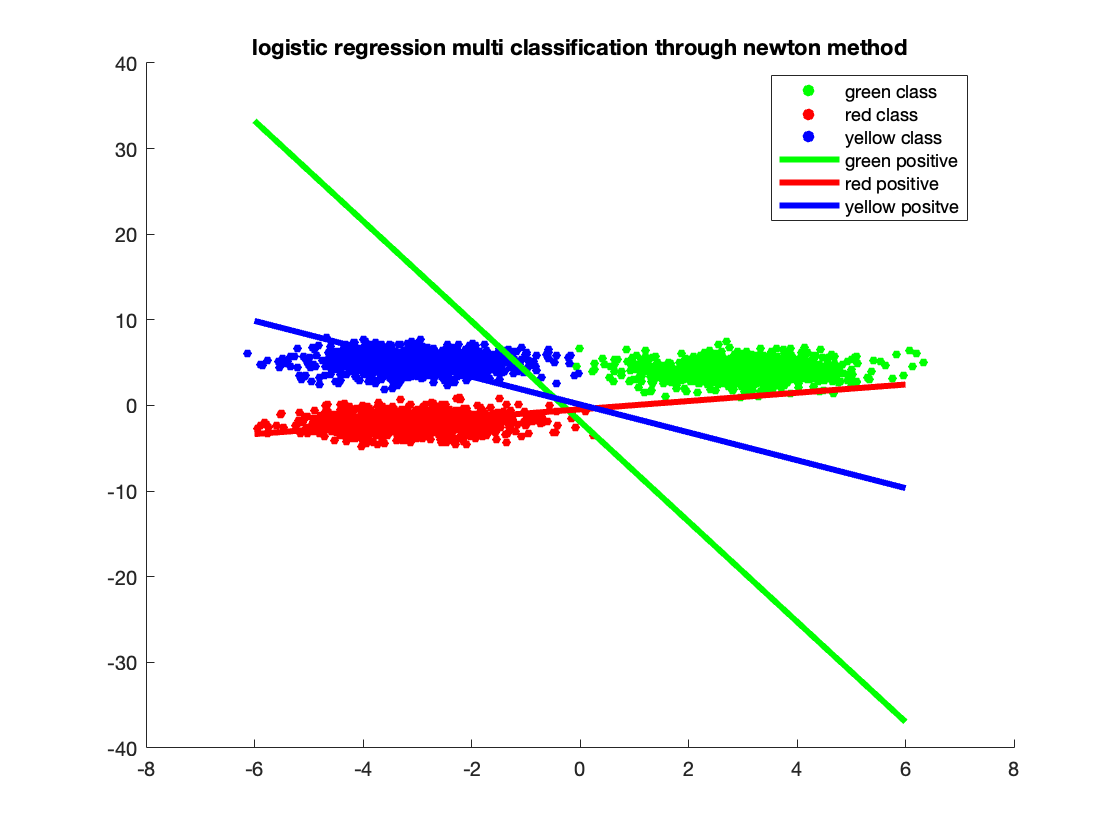

% specify sample amount, feature dimension, mean and covariance
x_range = -6:1:6;
n = 1000; % sample amout
dimension = 2;
k = 3;  % 3 classes
step = 5000; % optimization iterations
mu1 = [3;4];
co1 = [1 0; 0 1];
mu2 = [-3;-2];
co2 = [1 0; 0 1];
mu3 = [-3; 5];
co3 = [1 0; 0 1];

% generate same random samples each time
rng(1)
X1 = generate_gassian_data(n, dimension, mu1, co1);
X2 = generate_gassian_data(n, dimension, mu2, co2);
X3 = generate_gassian_data(n, dimension, mu3, co3);

% generate labels 1 for selected class and 0 for other two classed
y = generate_imbalance_labels(n, k);

% let X1 be positive 1
X = [X1, X2, X3; ones([1,k*n])];
weightA = logistic_regression_newton(X, y, step);
weightA = weightA./norm(weightA);
% let X2 be positive 1
X = [X2, X1, X3; ones([1,k*n])];
weightB = logistic_regression_newton(X, y, step);
weightB = weightB./norm(weightB);
% let X3 be positive 1
X = [X3, X1, X2; ones([1,k*n])];
weightC = logistic_regression_newton(X, y, step);
weightC = weightC./norm(weightC);

% scatter three gaussian class and plot three boudaries
scatter(X1(1,:), X1(2,:), ...
    'filled', "MarkerFaceColor",'g', "SizeData",20, 'DisplayName', 'class1')
hold on
scatter(X2(1,:), X2(2,:), ...
    'filled', "MarkerFaceColor",'r', "SizeData",20, 'DisplayName', 'class2')
scatter(X3(1,:), X3(2,:), ...
    'filled', "MarkerFaceColor",'b', "SizeData",20, 'DisplayName', 'class3')
plot(x_range, (-weightA(3) - weightA(1).*x_range)./weightA(2), "LineWidth", 3, "Color", 'g')
plot(x_range, (-weightB(3) - weightB(1).*x_range)./weightB(2), "LineWidth", 3, "Color", 'r')
plot(x_range, (-weightC(3) - weightC(1).*x_range)./weightC(2), "LineWidth", 3, "Color", 'b')
legend('green class', 'red class', 'yellow class', ...
    'green positive', 'red positive', 'yellow positve', "Location","best")
title('logistic regression multi classification through newton method')
hold off

## Evaluation step

% evaluation opitimized model on training set

% evalute each classify on X1 and combine
c11 = weightA' * [X1; ones(1, n)];
c12 = weightB' * [X1; ones(1, n)];
c13 = weightC' * [X1; ones(1, n)];
[~, a1] = max([c11; c12; c13]);
% evalute each classify on X2 and combine
c21 = weightA' * [X2; ones(1, n)];
c22 = weightB' * [X2; ones(1, n)];
c23 = weightC' * [X2; ones(1, n)];
[~, a2] = max([c21; c22; c23]);
% evalute each classify on X3 and combine
c31 = weightA' * [X3; ones(1, n)];
c32 = weightB' * [X3; ones(1, n)];
c33 = weightC' * [X3; ones(1, n)];
[~, a3] = max([c31; c32; c33]);

labels = [ones(1, n),ones(1, n)*2,ones(1, n)*3];
predict = [a1, a2, a3];

% compare actual labels and predicted labels through confushion matrix
cm = confusionmat(labels, predict)

cm =           14           0         986
           4         991           5
           0           0        1000


% calculate accuracy
accuray = sum(diag(cm))/sum(sum(cm))

accuray = 0.6683

function labels = generate_imbalance_labels(n, k)
    positive = ones([1, 1*n]);
    negtive = zeros([1, (k-1)*n]);
    labels = [positive, negtive];
end

% weight updated function
function weight = logistic_regression_newton(X, y, step)
    for i=1:step
        weight = randn(3,1);
        z = weight'*X;
        p = sig_fun(z);
        grad = X*(y'-p');
        hessian = -X*p'.*(1-p)*X';
        weight = weight - pinv(hessian)*grad;
    end
end
